## Course Example: Comparing Real Cost

Create a script to load and plot gasoline price data.

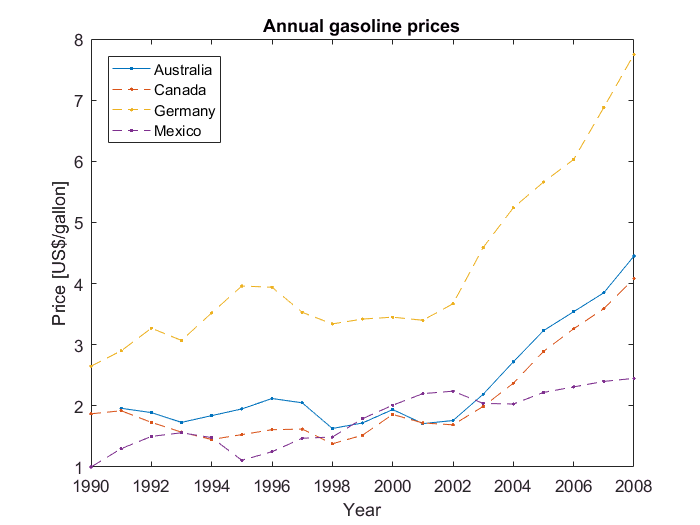

load gCosts
plot(Year,Australia,'.-')
hold on
plot(Year,Canada,'.--')
plot(Year,Germany,'.--')
plot(Year,Mexico,'.--')
hold off
legend(country,'Location','northwest')
title('Annual gasoline prices')
xlabel('Year')
ylabel('Price [US$/gallon]')

## Array Operations

Create and run a section in your script to convert the gasoline prices to comparable units – work hours (based on average income) per liter.

gal2lit = 0.2642;
Australia = gal2lit*Australia/hourlyAus;
Canada = gal2lit*Canada/hourlyCan;
Germany = gal2lit*Germany/hourlyGer;
Mexico = gal2lit*Mexico/hourlyMex;

Calculate the difference between Australian and Canadian cost.

AuCaDiff = Canada - Australia;

Calculate the average of Canadian and Mexican cost.

CaMxAvg = (Canada + Mexico)/2;

## Mathematical Functions

Calculate the absolute value of the difference between Australian and Canadian cost.

absDiff = abs(AuCaDiff);

View the elementary math functions.

doc elfun

## Statistical Functions

Find the greatest cost difference between Australia and Canada.

biggestDiff = max(absDiff)

biggestDiff = 0.0036

What was the average difference in gasoline cost between Australia and Canada?

avgDiff = mean(AuCaDiff)

avgDiff = NaN

Is the result what you expected? Modify the command to ignore NaNs.

avgDiff = mean(AuCaDiff,'omitNaN')

avgDiff = 2.2904e-05

View functions for data analysis.

doc datafun

## Indexing into Vectors

Extract the missing Australian price.

Aus90 = Australia(1)

Aus90 = NaN

When did the greatest cost difference between Australia and Canada occur?

[biggestDiff,idx] = max(absDiff);
Year(idx)

ans = 1996

## Changing Values in a Vector

Replace the missing Australian cost in 1990 with the Australian cost in 1991.

Australia(1) = Australia(2);

## Creating Vectors of Equally Spaced Values

Create a vector of years using the colon operator.

yrs = 1990:2008

yrs =         1990        1991        1992        1993        1994        1995        1996        1997        1998        1999        2000        2001        2002        2003        2004        2005        2006        2007        2008


Create a column vector of years.

yrs = (1990:2008)'

yrs =         1990
        1991
        1992
        1993
        1994
        1995
        1996
        1997
        1998
        1999


## Accessing Data in Vectors

Extract the prices in Mexico up to 2000, and from 2000 on.

Mex90s = Mexico(1:10)

Mex90s =     0.0380
    0.0493
    0.0569
    0.0592
    0.0562
    0.0421
    0.0474
    0.0558
    0.0566
    0.0679


Mex00s = Mexico(11:end)

Mex00s =     0.0763
    0.0835
    0.0850
    0.0774
    0.0771
    0.0843
    0.0877
    0.0911
    0.0930


Find the average annual gasoline cost change in Mexico in the 1990s and the 2000s.

MexAvgChange90s = mean(diff(Mex90s))

MexAvgChange90s = 0.0033

MexAvgChange00s = mean(diff(Mex00s))

MexAvgChange00s = 0.0021

Which were the five cheapest years for gasoline in Germany?

[sGer,sIdx] = sort(Germany);
sYear = Year(sIdx);
sYear(1:5)

ans =         1990
        1991
        1993
        1992
        1998


## Additional Vector Plot Types

Visualize the difference between Australian and Canadian gasoline costs.

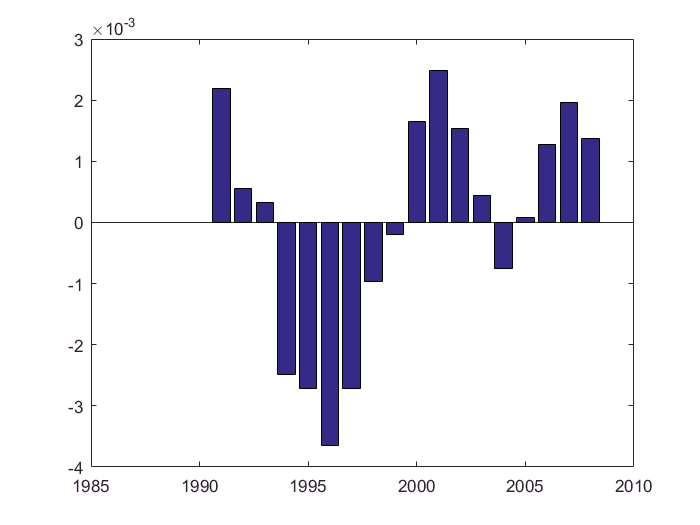

bar(Year,AuCaDiff)

Try some alternative visualizations.

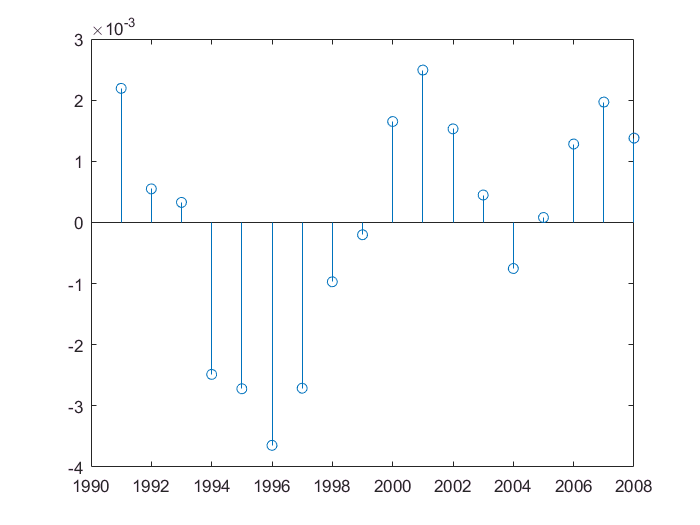

stem(Year,AuCaDiff)

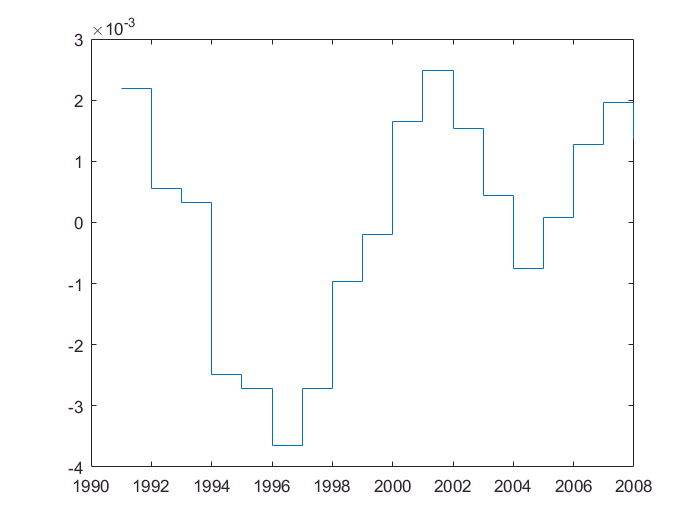

stairs(Year,AuCaDiff)

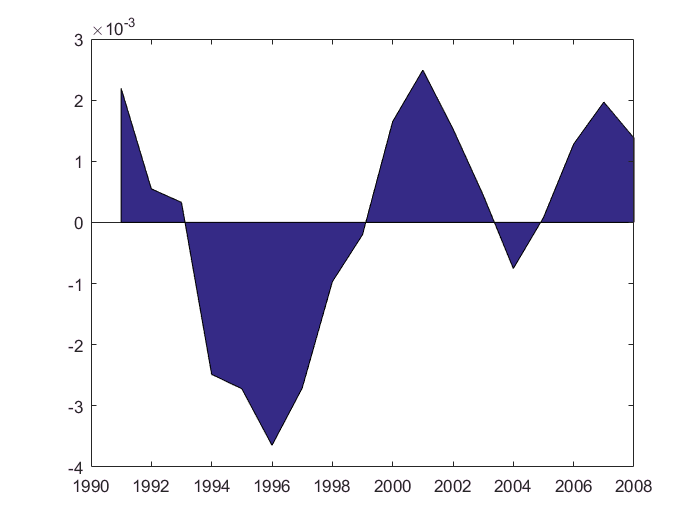

area(Year,AuCaDiff)

See the relationship between Australian and Canadian costs.

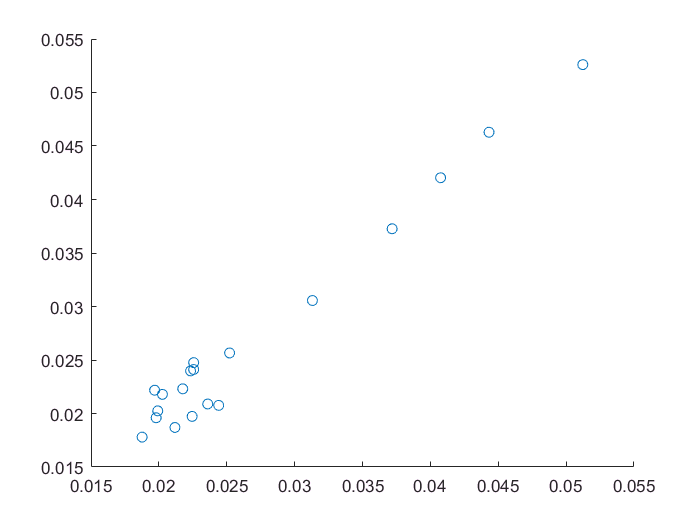

scatter(Australia,Canada)

Use the year to color the markers.

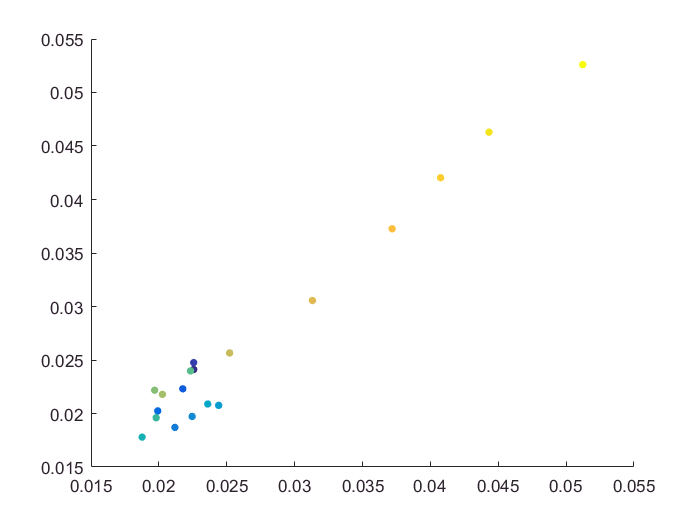

scatter(Australia,Canada,20,Year,'Filled')

## Axis Control

Adjust the limits on the horizontal axis.

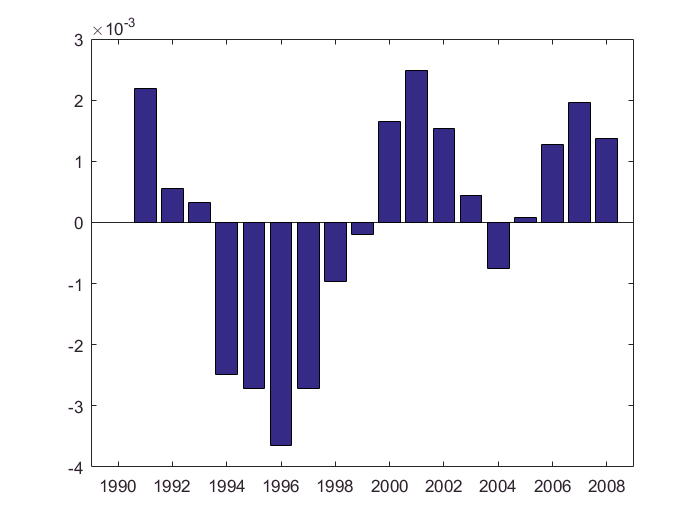

bar(Year,AuCaDiff)
xlim([1989 2009])

Add a 45-degree line to a scatter plot.

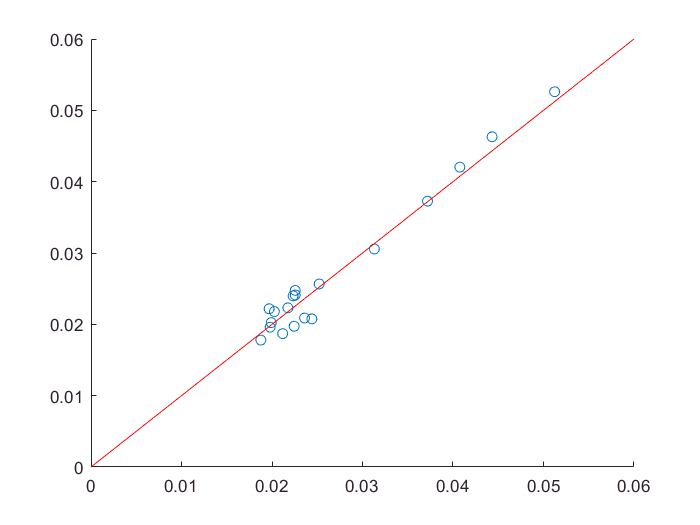

scatter(Australia,Canada)
xlim([0 0.06])
AuLimits = xlim;
hold on
plot(AuLimits,AuLimits,'r')
hold off